# **Jutted BMOCZ (J-BMOCZ) with Zero Rotation**

**Description:** In this example, we transmit a J-BMOCZ polynomial through an AWGN channel and decode under a random phase rotation of the received zeros. 

The example illustrates J-BMOCZ, template-based estimation of zero rotation, and the direct zero-testing (DiZeT) decoder. 

The following functions are used:

- 
$$\texttt{generateAllZeros()}$$


- 
$$\texttt{jbmoczMessageToPoly()}$$


- 
$$\texttt{getTemplate()}$$


- 
$$\texttt{correctPolysWithTemplate()}$$


- 
$$\texttt{standardDizet()}$$


**Before starting:** ensure that your working directory is the "\examples" folder.

Add the "\functions" folder to your MATLAB path.

clear; close all; clc;

% Get current path and parent directory
currentFolder = pwd;
parentFolder = fileparts(currentFolder);

% Add functions to current path
addpath(strcat(parentFolder, '\functions'))

Set the J-BMOCZ zero constellation parameters.

**Note:** for J-BMOCZ, the asymmetry factor is greater than one, i.e., $\zeta>1$.

K = 32;       % Number of zeros
R = 1.044;    % Radius
zeta = 1.15;  % Asymmetry factor

Generate a random $\texttt{K}$-bit message and map it to the corresponding zero pattern and J-BMOCZ polynomial using $\texttt{jbmoczMessageToPoly()}$.

Plot the TX zeros.

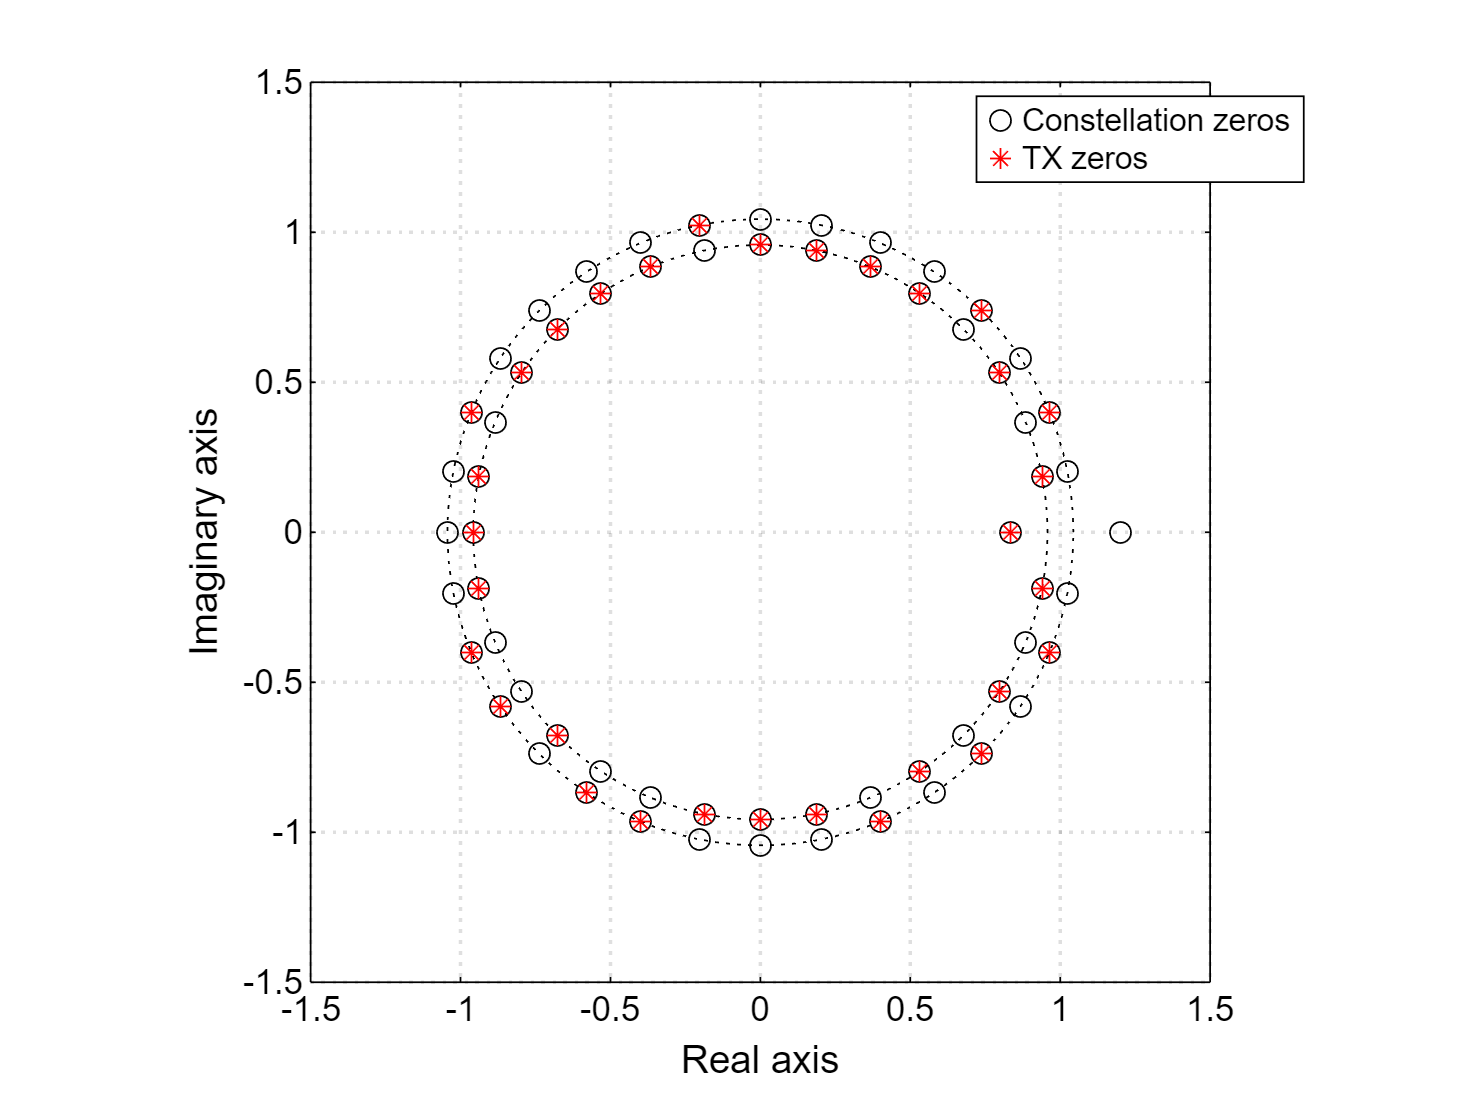

% Generate random binary message
messageTX = randi([0, 1], K, 1);

% Generate all zeros in the constellation
constellationZeros = generateAllZeros(K, R, zeta);

% Map message to zero pattern and J-BMOCZ polynomial
[polyTX, zerosTX] = jbmoczMessageToPoly(messageTX, R, zeta, K+1);

% Plot the TX zeros
theta = linspace(0, 2*pi, 100);
Router = R * exp(1j*theta); Rinner = 1/R * exp(1j*theta);

f1 = figure(1);
grid on; box on; hold on; axis square;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

lgd = legend; lgd.AutoUpdate = 'off';

plot(real(Rinner), imag(Rinner), 'k:')
plot(real(Router), imag(Router), 'k:')

lgd.AutoUpdate = 'on';

scatter(real(constellationZeros(:)), imag(constellationZeros(:)), 'ko', 'DisplayName', 'Constellation zeros')
scatter(real(zerosTX), imag(zerosTX), 'r*', 'DisplayName', 'TX zeros')

xlabel('Real axis')
ylabel('Imaginary axis')

lgd.Location = 'best';

Perturb the TX polynomial with AWGN (at an $E_\mathrm{b}/N_0$ of your choosing), and rotate its zeros through an angle $\phi\sim\mathcal{U}[0,2\pi]$. 

Plot the RX zeros.

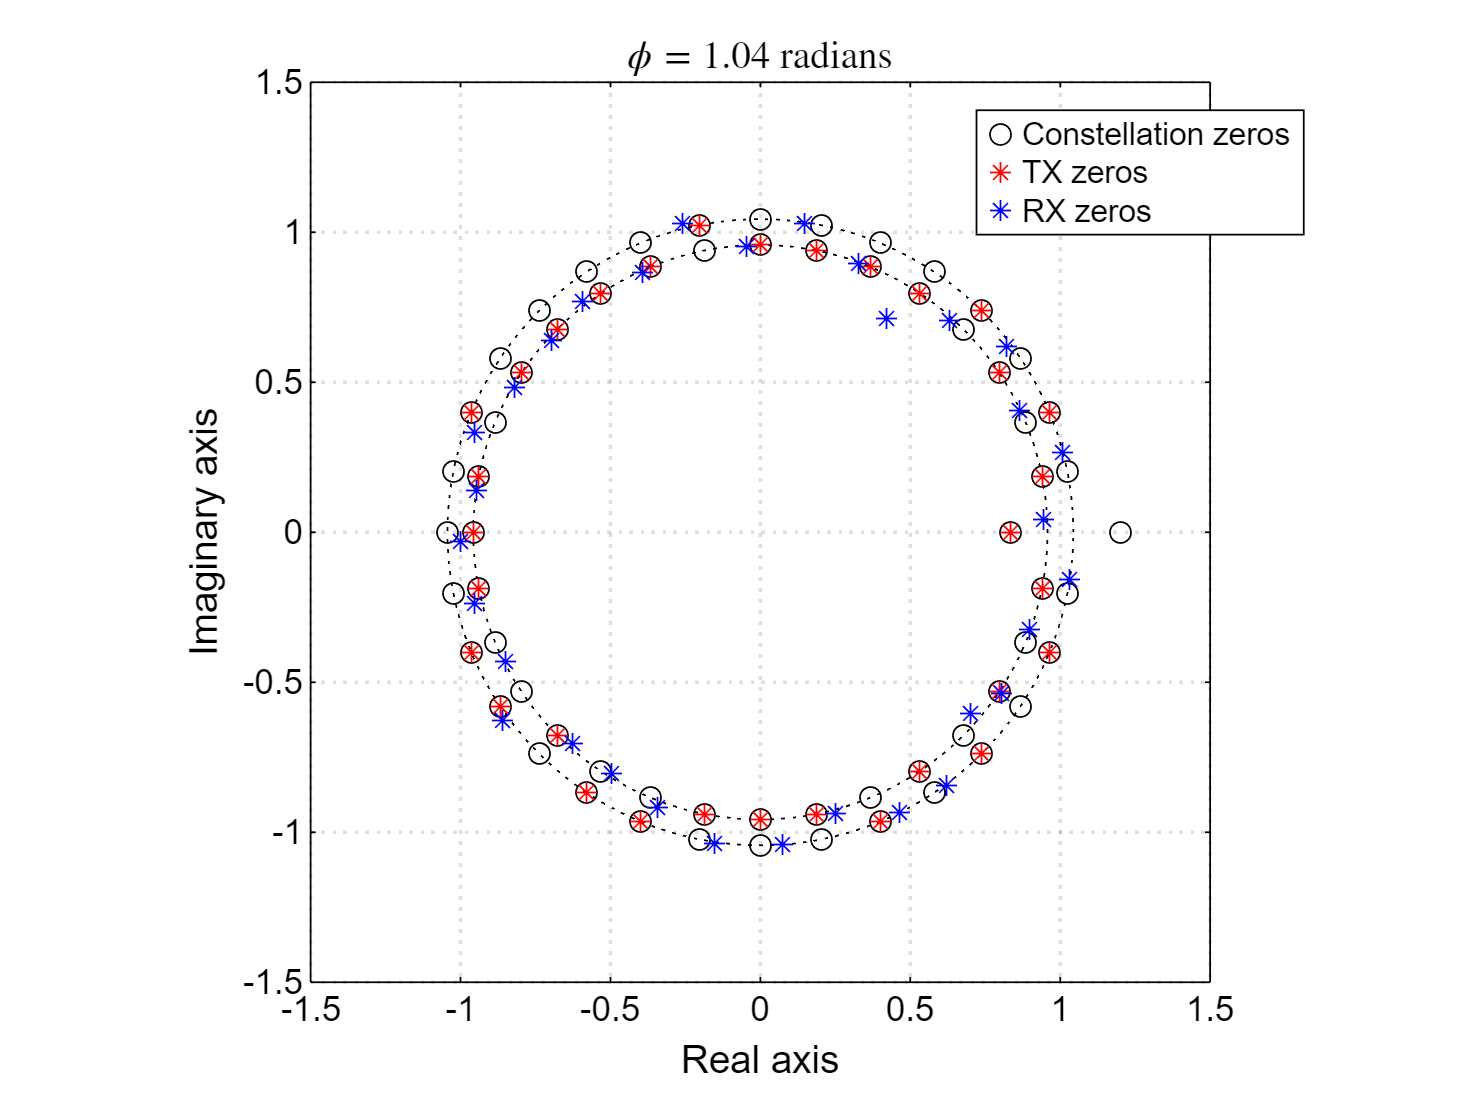

EbN0 = 12;  % dB

% Get N0 on a linear scale (here we assume Es = 1, i.e., the coefficient energy is K+1)
EsN0 = EbN0 + 10*log10(K/(K+1));
N0 = 10 ^ (-EsN0/10);

% Generate AWGN
w = sqrt(N0/2) * (randn(size(polyTX)) + 1j*randn(size(polyTX)));

% Get random phase angle (for zero rotation)
posAngles = linspace(0, 2*pi, 1000);
phi = posAngles(randi([1, 1000], 1, 1));

% Compute RX polynomial (and its roots)
polyRX = (polyTX + w) .* exp(1j*phi*(0:K)).';
zerosRX = roots(polyRX);

% Plot the RX zeros
scatter(real(zerosRX), imag(zerosRX), 'b*', 'DisplayName', 'RX zeros')
title(sprintf('$\\phi = %.2f$ radians', phi), 'Interpreter', 'latex')

Generate the J-BMOCZ template transform (and template matrix) with $\texttt{getTemplate()}$.

Use the template matrix to correct the zero rotation with $\texttt{correctPolysWithTemplate()}$.

Plot the TX and RX template transforms.

**Note:** the variable $\texttt{N}$ controls the resolution of $\hat{\phi}$, i.e., the resolution of the estimate of zero rotation. Specifically, the interval $[0,2\pi)$ is quantized into $\texttt{N}$ uniform bins.

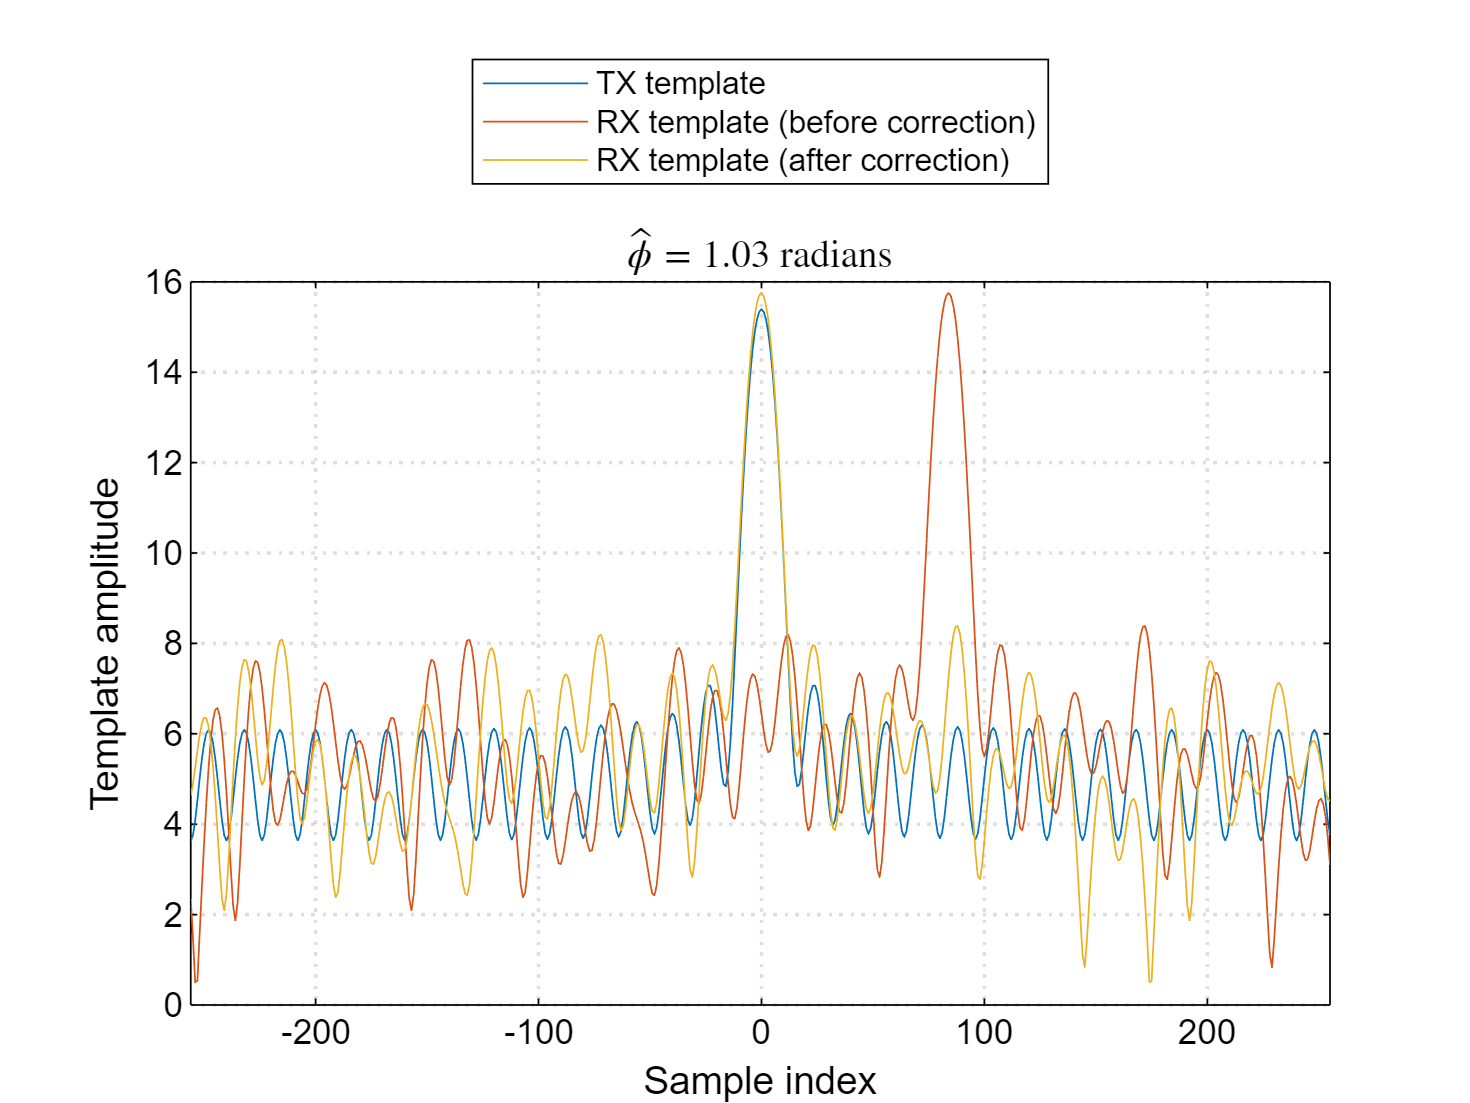

N = 512;  % Template resolution

% Get template transform and template matrix 
[templateVector, templateMat] = getTemplate(constellationZeros, K+1, N);

% Calculate RX template (before correcting zero rotation)
rxTemplate = abs(fft(polyRX, N));

% Correct zero rotation using template
[polyRXcorrected, phiHat] = correctPolysWithTemplate(polyRX, templateMat);

% Calculate RX template (after correcting zero rotation)
rxTemplateCorrected = abs(fft(polyRXcorrected, N));

% Plot template transforms
f2 = figure(2);
grid on; box on; hold on;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

n = -N/2:N/2-1;

plot(n, fftshift(templateVector), 'DisplayName', 'TX template')
plot(n, fftshift(rxTemplate), 'DisplayName', 'RX template (before correction)')
plot(n, fftshift(rxTemplateCorrected), 'DisplayName', 'RX template (after correction)')

xlabel('Sample index')
ylabel('Template amplitude')

xlim([min(n), max(n)])

lgd = legend;
lgd.Location = 'northoutside';

title(sprintf('$\\hat{\\phi} = %.2f$ radians', phiHat), 'Interpreter', 'latex')

Perform DiZeT decoding on the corrected polynomial using $\texttt{standardDizet()}$.

Print the number of bit errors.

% DiZeT decoding
messageRX = standardDizet(polyRXcorrected, K, constellationZeros, 0);

% Print the number of bit errors
bitErrors = sum(abs(messageRX - messageTX))

bitErrors = 0